Task One: Download and preprocessing image

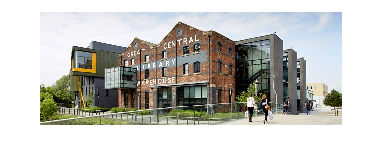

% load image, and convert to greyscale
RGB = imread("C:\Users\princ\OneDrive\Documents\MATLAB\ComputerVision\Week2\Resources\library.jpg");
figure; imshow(RGB);

size(RGB)

ans =    232   620     3


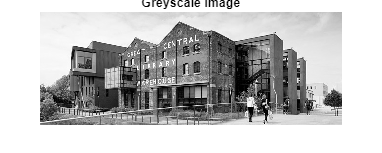


GREY = rgb2gray(RGB);
imshow(GREY); title('Greyscale Image');

Task Two: Sobel Filtering

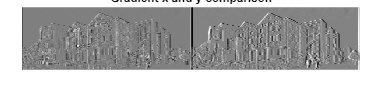

% Convert to double precision
GREY_DOUBLE = im2double(GREY);

% Declare the sobel filter
SOBEL_X = [[-1,0,1],[-2,0,2],[-1,0,1]];
SOBEL_Y = [[-1,-2,-1],[0,0,0],[1,2,1]];

%Filter the images with the kernel seperately
G_x = conv2(GREY_DOUBLE, SOBEL_X);
G_y = conv2(GREY_DOUBLE, SOBEL_Y);

% Display the 2 images side-by-side
imshowpair(G_x, G_y, 'montage'); title('Gradient x and y comparison');

Task Three: Gradient Magnitude

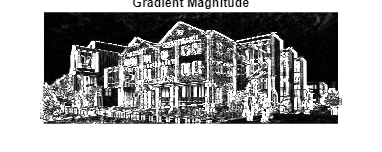

% Show gradient magnitude 
G = sqrt(G_y.^2 + G_x.^2);
imshow(G); title('Gradient Magnitude')

Task Four: Gaussian smoothing

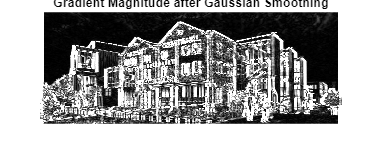

sigma = 0.0000001;
G = imgaussfilt(G, sigma);
imshow(G); title('Gradient Magnitude after Gaussian Smoothing')

Task 5: Lapacian of Gaussian

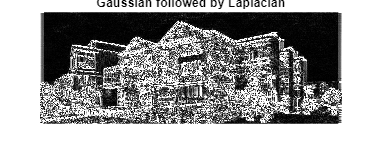

% Create Gaussian and Laplacian kernels using fspecial
hsize = [5 5];
alpha = 0.0001;
gaussian_kernel = fspecial('gaussian', hsize, sigma);
laplace_kernel = fspecial('laplacian', alpha);

% Convolve image with Gaussian kernel
c_gaussian = conv2(G, gaussian_kernel, 'same');
% Convolve result with Laplacian kernel
c_gaussian_laplace_result = conv2(c_gaussian, laplace_kernel, 'same');
imshow(abs(c_gaussian_laplace_result));
title('Gaussian followed by Laplacian');

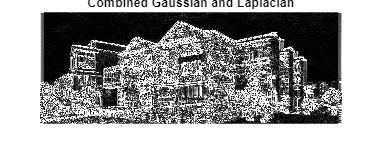


%% Convolve Gaussian kernel with Laplacian kernel
c_gaussian_lapacian = conv2(gaussian_kernel, laplace_kernel, 'same');
% Convolve the image with the resulting LoG kernel
c_laplace_gaussian_result = conv2(G, c_gaussian_lapacian, 'same');
% Display the result
imshow(abs(c_laplace_gaussian_result));
title('Combined Gaussian and Laplacian');

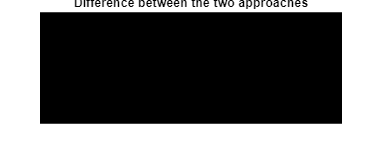


% Verify that the results of both approaches are equivalent
difference = abs(c_gaussian_laplace_result - c_laplace_gaussian_result);
imshow(difference);
title('Difference between the two approaches');